#### KINOVA Gen3 Manipulator

robot = loadrobot('kinovaGen3', 'DataFormat', 'row', "Gravity", [0 0 -9.81])

robot =   rigidBodyTree with properties:

     NumBodies: 8
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Shoulder_Link'  'HalfArm1_Link'  'HalfArm2_Link'  'ForeArm_Link'  'Wrist1_Link'  'Wrist2_Link'  'Bracelet_Link'  'EndEffector_Link'}
      BaseName: 'base_link'
       Gravity: [0 0 -9.8100]
    DataFormat: 'row'



currentRobotJConfig = homeConfiguration(robot)

currentRobotJConfig =      0     0     0     0     0     0     0



numJoints = numel(currentRobotJConfig)

numJoints = 7

endEffector = "EndEffector_Link"

endEffector = "EndEffector_Link"


timeStep = 0.1 % seconds

timeStep = 0.1000

toolSpeed = 0.1 % m/s

toolSpeed = 0.1000


jointInit = currentRobotJConfig

jointInit =      0     0     0     0     0     0     0


taskInit = getTransform(robot, jointInit, endEffector)

taskInit =     1.0000         0         0         0
         0    1.0000   -0.0000   -0.0249
         0    0.0000    1.0000    1.1854
         0         0         0    1.0000



taskFinal = trvec2tform([0.4 0 0.6])*axang2tform([0 1 0 pi])

taskFinal =    -1.0000         0    0.0000    0.4000
         0    1.0000         0         0
   -0.0000         0   -1.0000    0.6000
         0         0         0    1.0000


#### Generate Task-Space Trajectory

distance = norm(tform2trvec(taskInit) - tform2trvec(taskFinal))

distance = 0.7094


initTime = 0

initTime = 0

finalTime = (distance/toolSpeed) - initTime

finalTime = 7.0943

trajTimes = initTime: timeStep: finalTime

trajTimes =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


timeInterval = [trajTimes(1); trajTimes(end)]

timeInterval =      0
     7



[taskWayPoints, taskVelocities] = transformtraj(taskInit, taskFinal, timeInterval, trajTimes)

taskWayPoints = taskWayPoints(:,:,1) =

    1.0000         0         0         0
         0    1.0000   -0.0000   -0.0249
         0    0.0000    1.0000    1.1854
         0         0         0    1.0000


taskWayPoints(:,:,2) =

    0.9990    0.0000    0.0449    0.0057
    0.0000    1.0000   -0.0000   -0.0245
   -0.0449    0.0000    0.9990    1.1770
         0         0         0    1.0000


taskWayPoints(:,:,3) =

    0.9960    0.0000    0.0896    0.0114
    0.0000    1.0000   -0.0000   -0.0241
   -0.0896    0.0000    0.9960    1.1687
         0         0         0    1.0000


taskWayPoints(:,:,4) =

    0.9909    0.0000    0.1342    0.0171
    0.0000    1.0000   -0.0000   -0.0238
   -0.1342    0.0000    0.9909    1.1603
         0         0         0    1.0000


taskWayPoints(:,:,5) =

    0.9839    0.0000    0.1786    0.0229
    0.0000    1.0000   -0.0000   -0.0234
   -0.1786    0.0000    0.9839    1.1519
         0         0         0    1.0000


taskWayPoints(:,:,6) =

    0.9749

taskVelocities =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488    0.4488  

#### Control Task-Space Motion

tsMotionModel = taskSpaceMotionModel('RigidBodyTree', robot, 'EndEffectorName', 'EndEffector_Link')

tsMotionModel =   taskSpaceMotionModel with properties:

      RigidBodyTree: [1×1 rigidBodyTree]
    EndEffectorName: 'EndEffector_Link'
       JointDamping: [1 1 1 1 1 1 1]
         MotionType: 'PDControl'
                 Kp: [6×6 double]
                 Kd: [6×6 double]



tsMotionModel.Kp(1: 3, 1: 3) = 0

tsMotionModel =   taskSpaceMotionModel with properties:

      RigidBodyTree: [1×1 rigidBodyTree]
    EndEffectorName: 'EndEffector_Link'
       JointDamping: [1 1 1 1 1 1 1]
         MotionType: 'PDControl'
                 Kp: [6×6 double]
                 Kd: [6×6 double]


tsMotionModel.Kd(1: 3, 1: 3) = 0

tsMotionModel =   taskSpaceMotionModel with properties:

      RigidBodyTree: [1×1 rigidBodyTree]
    EndEffectorName: 'EndEffector_Link'
       JointDamping: [1 1 1 1 1 1 1]
         MotionType: 'PDControl'
                 Kp: [6×6 double]
                 Kd: [6×6 double]



q0 = currentRobotJConfig

q0 =      0     0     0     0     0     0     0


qd0 = zeros(size(q0))

qd0 =      0     0     0     0     0     0     0



[tTask, stateTask] = ode15s(@(t, state) exampleHelperTimeBasedTaskInputs(tsMotionModel, timeInterval, taskInit, taskFinal, t, state), timeInterval, [q0; qd0])

tTask =          0
    0.0128
    0.0257
    0.0385
    0.1029
    0.1674
    0.2318
    0.2962
    0.4490
    0.6018


stateTask =          0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0002   -0.0002
    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0004   -0.0003
    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0006   -0.0005
    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001    0.0001    0.0016   -0.0013
    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001   -0.0002    0.0002    0.0026   -0.0021
    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001   -0.0002    0.0002    0.0036   -0.0028
 

#### Generate Joint-Space Trajectory

ik = inverseKinematics('RigidBodyTree', robot)

ik =   inverseKinematics with properties:

       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


ik.SolverParameters.AllowRandomRestart = false

ik =   inverseKinematics with properties:

       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


weights = [1 1 1 1 1 1]

weights =      1     1     1     1     1     1



initialGuess = jointInit

initialGuess =      0     0     0     0     0     0     0


jointFinal = ik(endEffector, taskFinal, weights, initialGuess)

jointFinal =   -25.9308    0.6770  -10.7459    1.1478   11.8130    2.0500  -18.1688



wrappedJointFinal = wrapToPi(jointFinal)

wrappedJointFinal =    -0.7981    0.6770    1.8205    1.1478   -0.7534    2.0500    0.6807



ctrlPoints = [jointInit' wrappedJointFinal']

ctrlPoints =          0   -0.7981
         0    0.6770
         0    1.8205
         0    1.1478
         0   -0.7534
         0    2.0500
         0    0.6807


jointConfigArray = cubicpolytraj(ctrlPoints, timeInterval, trajTimes)

jointConfigArray =          0   -0.0005   -0.0019   -0.0043   -0.0075   -0.0116   -0.0166   -0.0223   -0.0289   -0.0362   -0.0442   -0.0529   -0.0623   -0.0724   -0.0830   -0.0942   -0.1060   -0.1183   -0.1312   -0.1445   -0.1582   -0.1724   -0.1869   -0.2019   -0.2171   -0.2327   -0.2485   -0.2646   -0.2809   -0.2974   -0.3141   -0.3309   -0.3479   -0.3649   -0.3819   -0.3990   -0.4161   -0.4332   -0.4502   -0.4671   -0.4840   -0.5006   -0.5172   -0.5335   -0.5496   -0.5654   -0.5810   -0.5962   -0.6111   -0.6257
         0    0.0004    0.0016    0.0036    0.0064    0.0099    0.0141    0.0190    0.0245    0.0307    0.0375    0.0449    0.0529    0.0614    0.0704    0.0799    0.0899    0.1004    0.1113    0.1226    0.1342    0.1462    0.1586    0.1712    0.1842    0.1974    0.2108    0.2245    0.2383    0.2523    0.2665    0.2807    0.2951    0.3095    0.3240    0.3385    0.3530    0.3675    0.3819    0.3963    0.4105    0.4247    0.4387    0.4525    0.4662    0.4796    0.4928    0.5058

jointWaypoints = bsplinepolytraj(jointConfigArray, timeInterval, 1)

jointWaypoints =    -0.0505
    0.0428
    0.1152
    0.0726
   -0.0477
    0.1297
    0.0431


#### Control Joint-Space Trajectory

jsMotionModel = jointSpaceMotionModel('RigidBodyTree', robot, 'MotionType', 'PDControl')

jsMotionModel =   jointSpaceMotionModel with properties:

       RigidBodyTree: [1×1 rigidBodyTree]
    NaturalFrequency: [10 10 10 10 10 10 10]
        DampingRatio: [1 1 1 1 1 1 1]
                  Kp: [7×7 double]
                  Kd: [7×7 double]
          MotionType: 'PDControl'



q0 = currentRobotJConfig

q0 =      0     0     0     0     0     0     0


qd0 = zeros(size(q0))

qd0 =      0     0     0     0     0     0     0



[tJoint, stateJoint] = ode15s(@(t, state) exampleHelperTimeBasedJointInputs(jsMotionModel, timeInterval, jointConfigArray, t, state), timeInterval, [q0; qd0])

tJoint =          0
    0.0164
    0.0328
    0.0492
    0.1369
    0.2247
    0.3124
    0.4001
    0.5917
    0.7832


stateJoint =          0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0001    0.0000    0.0001
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0001   -0.0000    0.0002   -0.0000   -0.0002    0.0000    0.0002
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0001   -0.0000    0.0002   -0.0000   -0.0003    0.0000    0.0004
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0002   -0.0000    0.0006   -0.0000   -0.0008    0.0001    0.0010
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0004   -0.0000    0.0010   -0.0000   -0.0014    0.0001    0.0016
   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0005   -0.0000    0.0014   -0.0000   -0.0019    0.0002    0.0021


#### Visualize and Compare Robot Trajectories

show(robot, currentRobotJConfig, 'PreservePlot', false, 'Frames', 'off')

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


hold on
axis([-1 1 -1 1 -0.1 1.5])

for i = 1: length(trajTimes)
    % Current time
    tNow = trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current
    % time
    configNow = interp1(tTask, stateTask(:, 1: numJoints), tNow);
    poseNow = getTransform(robot, configNow, endEffector);
    show(robot, configNow, 'PreservePlot', false, 'Frames', 'off');
    taskSpaceMarker = plot3(poseNow(1, 4), poseNow(2, 4), poseNow(3, 4), 'b.', 'MarkerSize', 20);
    drawnow;
end

% Return to initial configuration
show(robot, currentRobotJConfig, 'PreservePlot', false, 'Frames', ['off'])

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


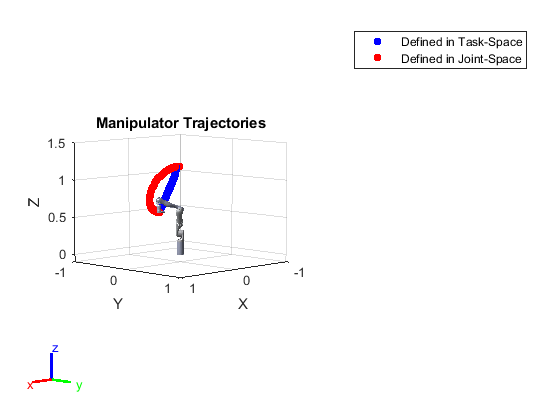


for i = 1: length(trajTimes)
    % Current time
    tNow = trajTimes(i);
    % Interpolate simulated joit positions to get configuration at current
    % time.
    configNow = interp1(tJoint, stateJoint(:, 1: numJoints), tNow);
    poseNow = getTransform(robot, configNow, endEffector);
    show(robot, configNow, 'PreservePlot', false, 'Frames', 'off');
    jointSpaceMarker = plot3(poseNow(1, 4), poseNow(2, 4), poseNow(3, 4), 'r.', 'MarkerSize', 20);
    drawnow;
end

% Add a legend and title
legend([taskSpaceMarker jointSpaceMarker], {'Defined in Task-Space', 'Defined in Joint-Space'})
title('Manipulator Trajectories')